## **Pre-processing the output data from the Hwa lab simulation**

% adding cross section to 3D scatter
global plot_range thickness i_cells;
plot_range = [-100 100 -100 100 0 35];
i_cells =118;
for n = 1:4
    file_path = sprintf('outputs/data_4/Cells%d/%d.txt',n,i_cells);
    if n == 1
        cells = importdata(file_path);
    else
        cells = cat(1,cells,importdata(file_path));
    end
end
x1 = cells(:,4);
x2 = cells(:,7);
y1 = cells(:,5);
y2 = cells(:,8);
z1 = cells(:,6);
z2 = cells(:,9);
lengths = cells(:,10);
pole_age_p = cells(:,27); % p age
pole_age_q = cells(:,28); % q age
pole_age_older = max(pole_age_p, pole_age_q);

avg_pole_age = (pole_age_p+pole_age_q)/2; % average pole age for cells
% average co-ordinates
x = (x1 + x2)/2;
y = (y1 + y2)/2;
z = (z1 + z2)/2;

%radial distance of cell
%Using the "." will effectively perform element-by-element mathematical operations
r = sqrt(x.^2 + y.^2);

**Set the size of the dots used in all subsequent scatter plots, and the thickness of all planar cross sections**

global thickness dot_size;
dot_size =4;
thickness =1;

## Cell Age

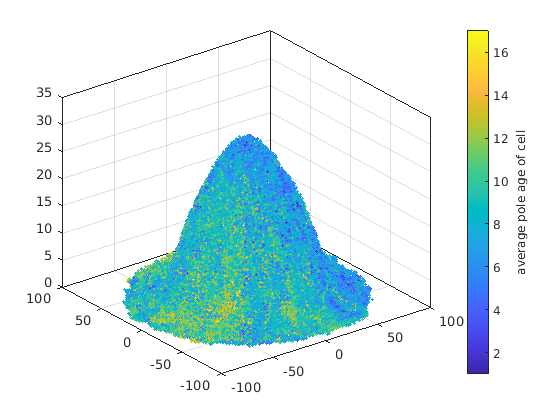

plt.color_scatter(x,y,z,dot_size,pole_age_older, "average pole age of cell")

cross sections of the above plot in all 3 principle directions

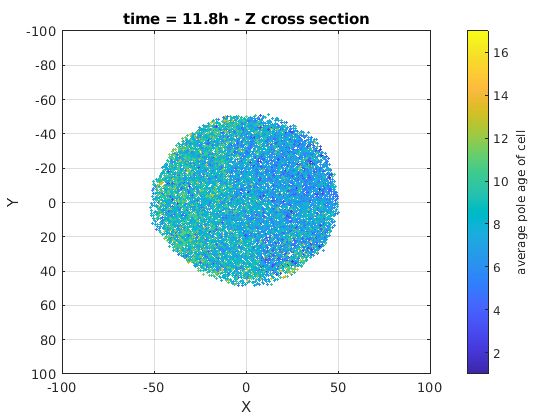

z_cut =12;
plt.color_scatter(x,y,z,dot_size,pole_age_older, "average pole age of cell", 'Z',z_cut)

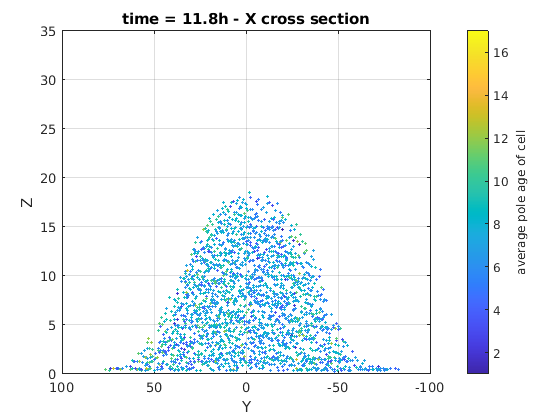

x_cut =38;
plt.color_scatter(x,y,z,dot_size,pole_age_older, "average pole age of cell", 'X',x_cut)

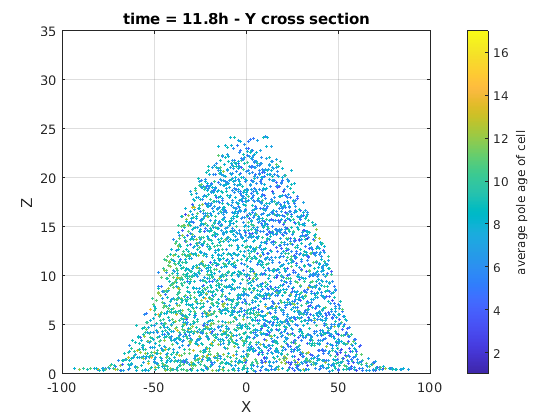

y_cut =22;
plt.color_scatter(x,y,z,dot_size,pole_age_older, "average pole age of cell", 'Y',y_cut)

### age plot trimmed to a radius

r_cut_age =28;
tube_thickness_age = 1;
i = find(r>r_cut_age & r<(r_cut_age+tube_thickness_age));

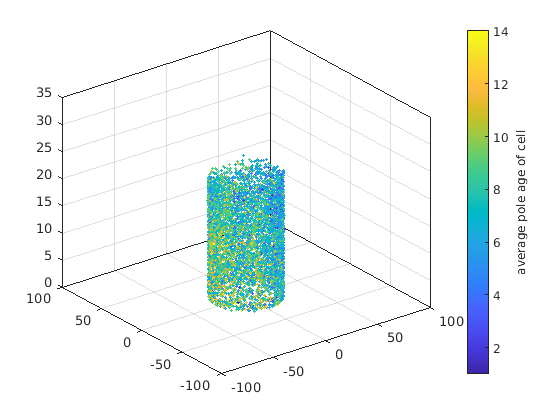

plt.color_scatter(x(i),y(i),z(i),dot_size,pole_age_older(i), "average pole age of cell")

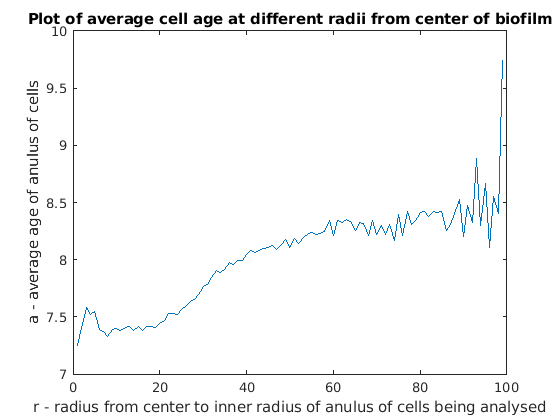

res = 1; %thickness of tubes being analysed
max_r = 100;
r_range = 1:res:(max_r-res); %https://uk.mathworks.com/help/matlab/ref/colon.html
avg_age = r_range;

num_cells_in_ring = r_range;
cell_density_in_ring = r_range;
for i = 1:length(r_range)
    ring_indeces = find(r>r_range(i) & r<(r_range(i)+res));
    avg_age(i) = mean(pole_age_older(ring_indeces), 'all');
    
    num_cells_in_ring(i) = length(ring_indeces);
    cell_density_in_ring(i) = num_cells_in_ring(i)/(2*pi*r_range(i));
end
plot(r_range,avg_age)

title('Plot of average cell age at different radii from center of biofilm')
xlabel('r - radius from center to inner radius of anulus of cells being analysed')
ylabel('a - average age of anulus of cells')

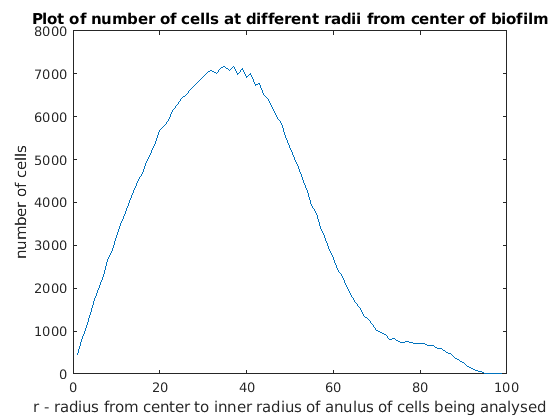

plot(r_range,num_cells_in_ring)

title('Plot of number of cells at different radii from center of biofilm')
xlabel('r - radius from center to inner radius of anulus of cells being analysed')
ylabel('number of cells')

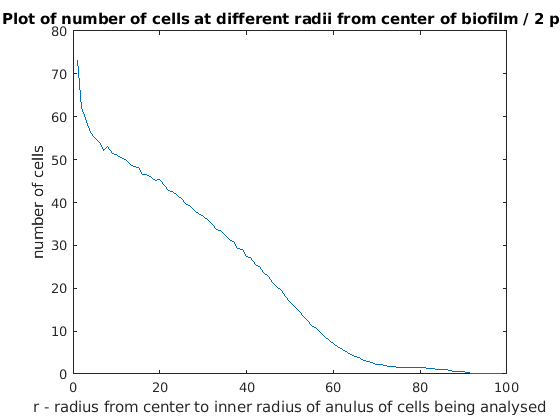


plot(r_range,cell_density_in_ring)

title('Plot of number of cells at different radii from center of biofilm / 2 pi r')
xlabel('r - radius from center to inner radius of anulus of cells being analysed')
ylabel('number of cells')

## Cell Length - scatter

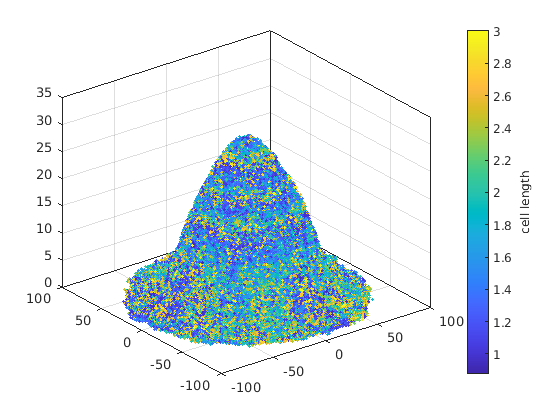

plt.color_scatter(x,y,z,dot_size,lengths, "cell length")

cross sections of the above plot in all 3 principle directions

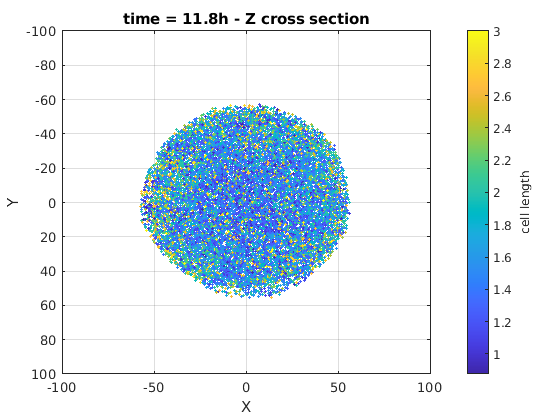

z_cut =8;
plt.color_scatter(x,y,z,dot_size,lengths, "cell length",'Z',z_cut)

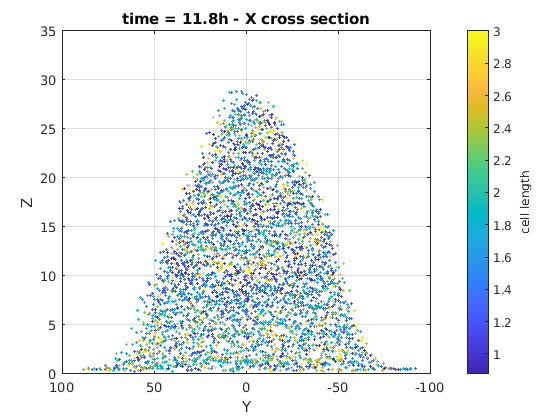

x_cut =8;
plt.color_scatter(x,y,z,dot_size,lengths, "cell length",'X',x_cut)

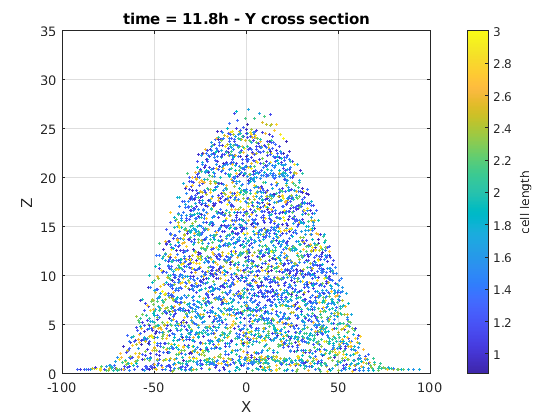

y_cut =15;
plt.color_scatter(x,y,z,dot_size,lengths, "cell length",'Y',y_cut)

length plot trimmed to a radius

r_cut_length =28;
tube_thickness_length = 1;
i = find(r>r_cut_length & r<(r_cut_length+tube_thickness_length));

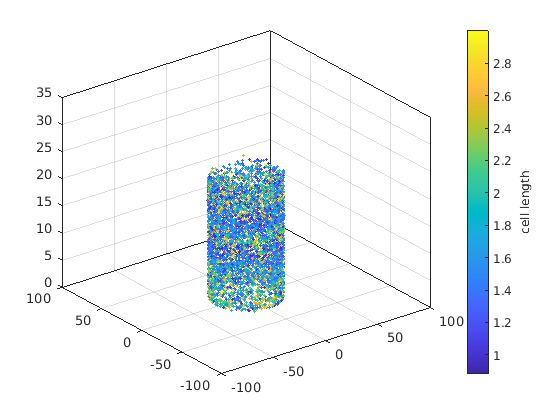

plt.color_scatter(x(i),y(i),z(i),dot_size,lengths(i), "cell length")

graphing average cell length for a certain radius as a 2d plot

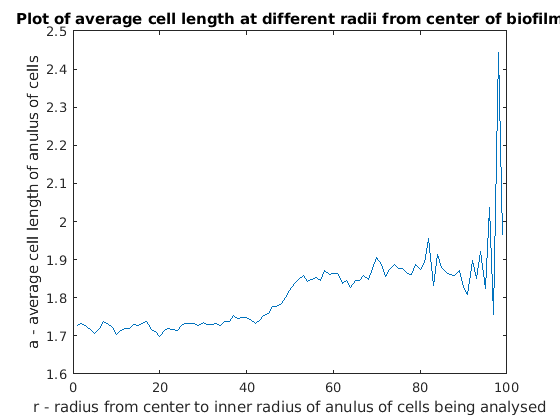

res = 1; %thickness of tubes being analysed
max_r = 100;
r_range = 1:res:(max_r-res); %https://uk.mathworks.com/help/matlab/ref/colon.html
avg_length = r_range;
for i = 1:length(r_range)
    ring_indeces = find(r>r_range(i) & r<(r_range(i)+res));
    avg_length(i) = mean(lengths(ring_indeces), 'all');
end
plot(r_range,avg_length)

title('Plot of average cell length at different radii from center of biofilm')
xlabel('r - radius from center to inner radius of anulus of cells being analysed')
ylabel('a - average cell length of anulus of cells')

## Experimental

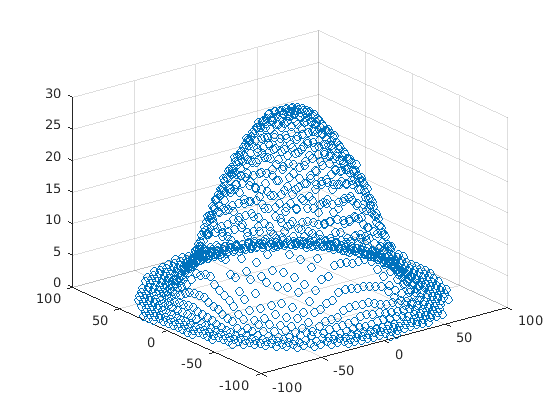

res = 5;
%find top surface of biofilm
xq = -100:res:100;
yq = -100:res:100;
zq = -100:res:100;
z_top = [0,0,0];
for i = 1:numel(xq);
    for j = 1:numel(yq);
        indices_in_square = find(x<xq(i)+res & x>xq(i)-res & y<yq(j)+res & y>yq(j)-res);
        if not(isempty(indices_in_square))
            new = [xq(i),yq(j),max(z(indices_in_square))];
            z_top = [z_top;new];
        end
    end
end
z_top(1,:) = []; %remove inital origin point - find better way to setup matrix
scatter3(z_top(:,1), z_top(:,2), z_top(:,3))

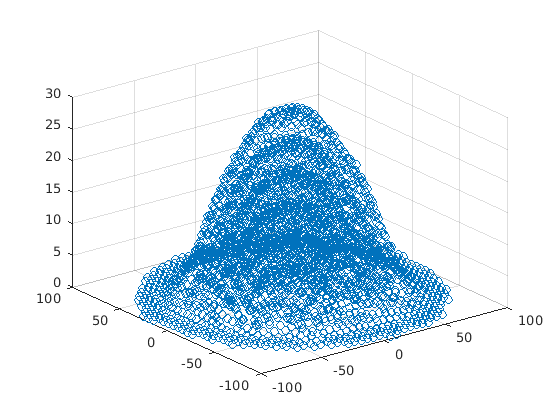

len = numel(z_top(:,1));
data = [0,0,0];
for i = 1:len
    pnt = z_top(i,:);
    while pnt(3) > 0
        data = [data;pnt];
        pnt(3) = pnt(3) - res;
    end
end
data(1,:) = [];
scatter3(data(:,1),data(:,2),data(:,3))

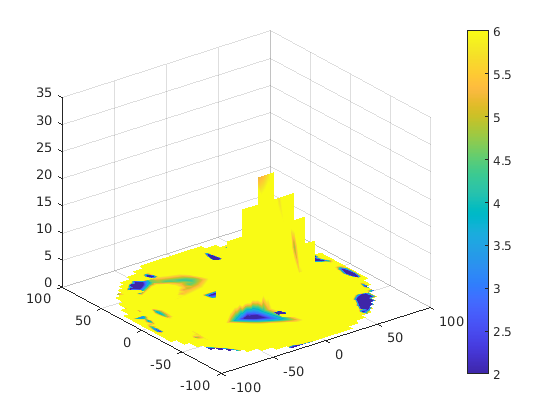

rng default;
%P = -2.5 + 5*rand([200 3]);
%v = sin(P(:,1).^2 + P(:,2).^2 + P(:,3).^2)./(P(:,1).^2+P(:,2).^2+P(:,3).^2);

F = scatteredInterpolant(x,y,z,pole_age_older);

%vq = F(data(:,1),data(:,2),data(:,3));
x_scale = -100:5:100;
y_scale = -100:5:100;
z_scale = 0:5:50;
[xq,yq,zq] = meshgrid(-100:5:100, -100:5:100, 0:5:50);

% set color to none if not under biofilm surface
vq = F(xq,yq,zq);
for a = 1:numel(z_top(:,1));
    pnt = z_top(a,:);
    in_x = find(x_scale == pnt(1));
    in_y = find(y_scale == pnt(2));
    for in_z = 1:numel(z_scale);
        if z_scale(in_z) > pnt(3)
            vq(in_x,in_y,in_z) = nan;
        end
    end
end
max_r = 100;
for in_x = 1:numel(x_scale)
    for in_y = 1:numel(y_scale)
        for in_z = 1:numel(z_scale)
            if x_scale(in_x)^2 + y_scale(in_y)^2 > max_r^2
                vq(in_x,in_y,in_z) = nan;
            end
        end
    end
end

xslice = -100;
yslice = -28;
zslice = 0;
slice(xq,yq,zq,vq,xslice,yslice,zslice)
colorbar
caxis([2,6])
view(3);
axis on;
axis(plot_range);
grid on;
shading interp;

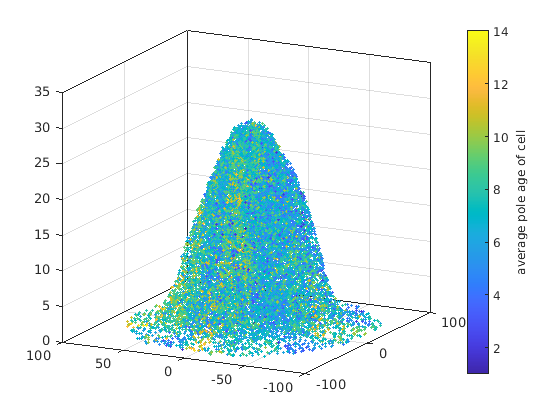

points = [x y z pole_age_older];
[u, s, v] = svd(points, 'econ');
num_points = 24660;
u1 = u(1:num_points,:);
a = u1*s*transpose(v);
xc = a(:,1);
yc = a(:,2);
zc = a(:,3);
vc = a(:,4);
plt.color_scatter(xc,yc,zc,dot_size,vc, "average pole age of cell")